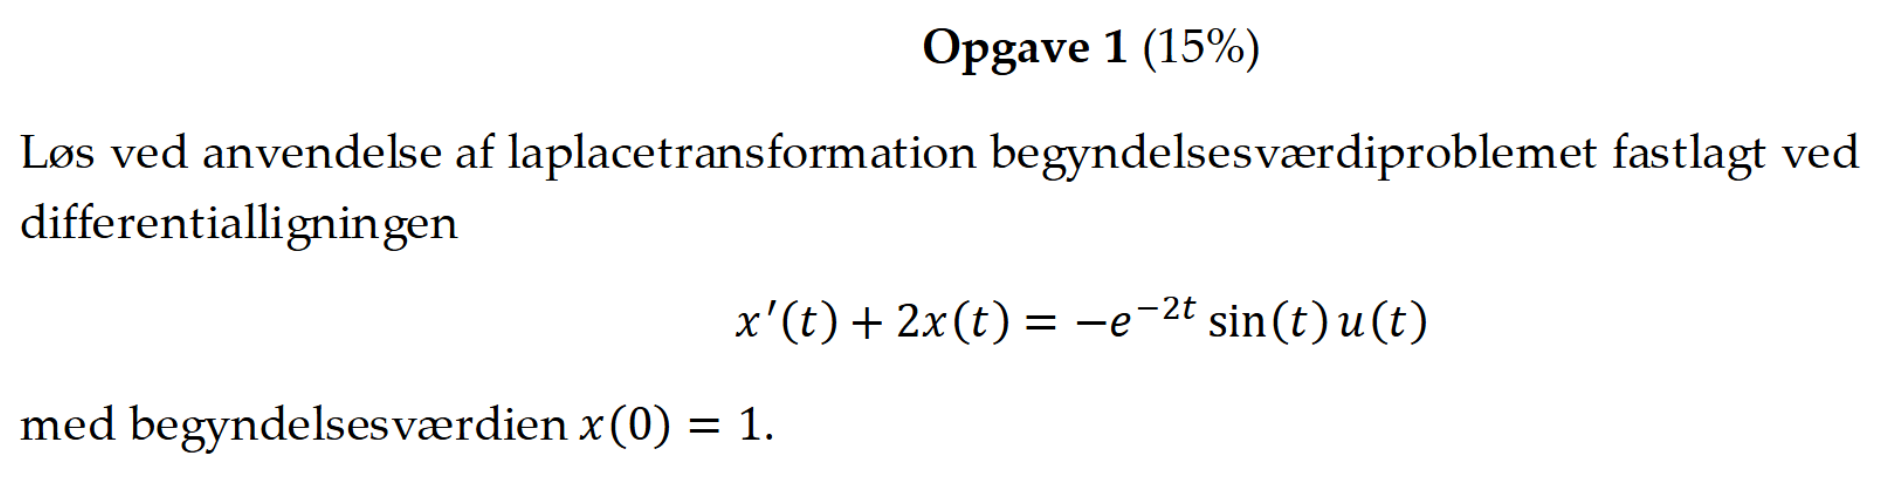

clear all; clc;

disp('=================================================================');
disp('OPGAVE 1: Løsning af differentialligning med Laplace-transformation');
disp('=================================================================');
disp(' ');

syms t s;

% Input signal med korrekt fortegn
input = -exp(-2*t)*sin(t);
[U_s, ~] = ElektroMatBibTrinvis.laplaceMedForklaring(input, t, s);

% Overføringsfunktion fra differentialligning x'(t) + 2x(t) = u(t)
[num, den, ~] = ElektroMatBibTrinvis.diffLigningTilOverfoeringsfunktionMedForklaring([1], [1, 2]);
H_s = poly2sym(num, s) / poly2sym(den, s);

% Total system med begyndelsesværdi x(0) = 1
X_s_total = H_s * U_s + H_s * 1;  % Forced response + initial condition
[x_t, ~] = ElektroMatBibTrinvis.inversLaplaceMedForklaring(X_s_total, s, t);

disp('Løsningen på differentialligningen er:');
disp(['x(t) = ' char(simplify(x_t))]);

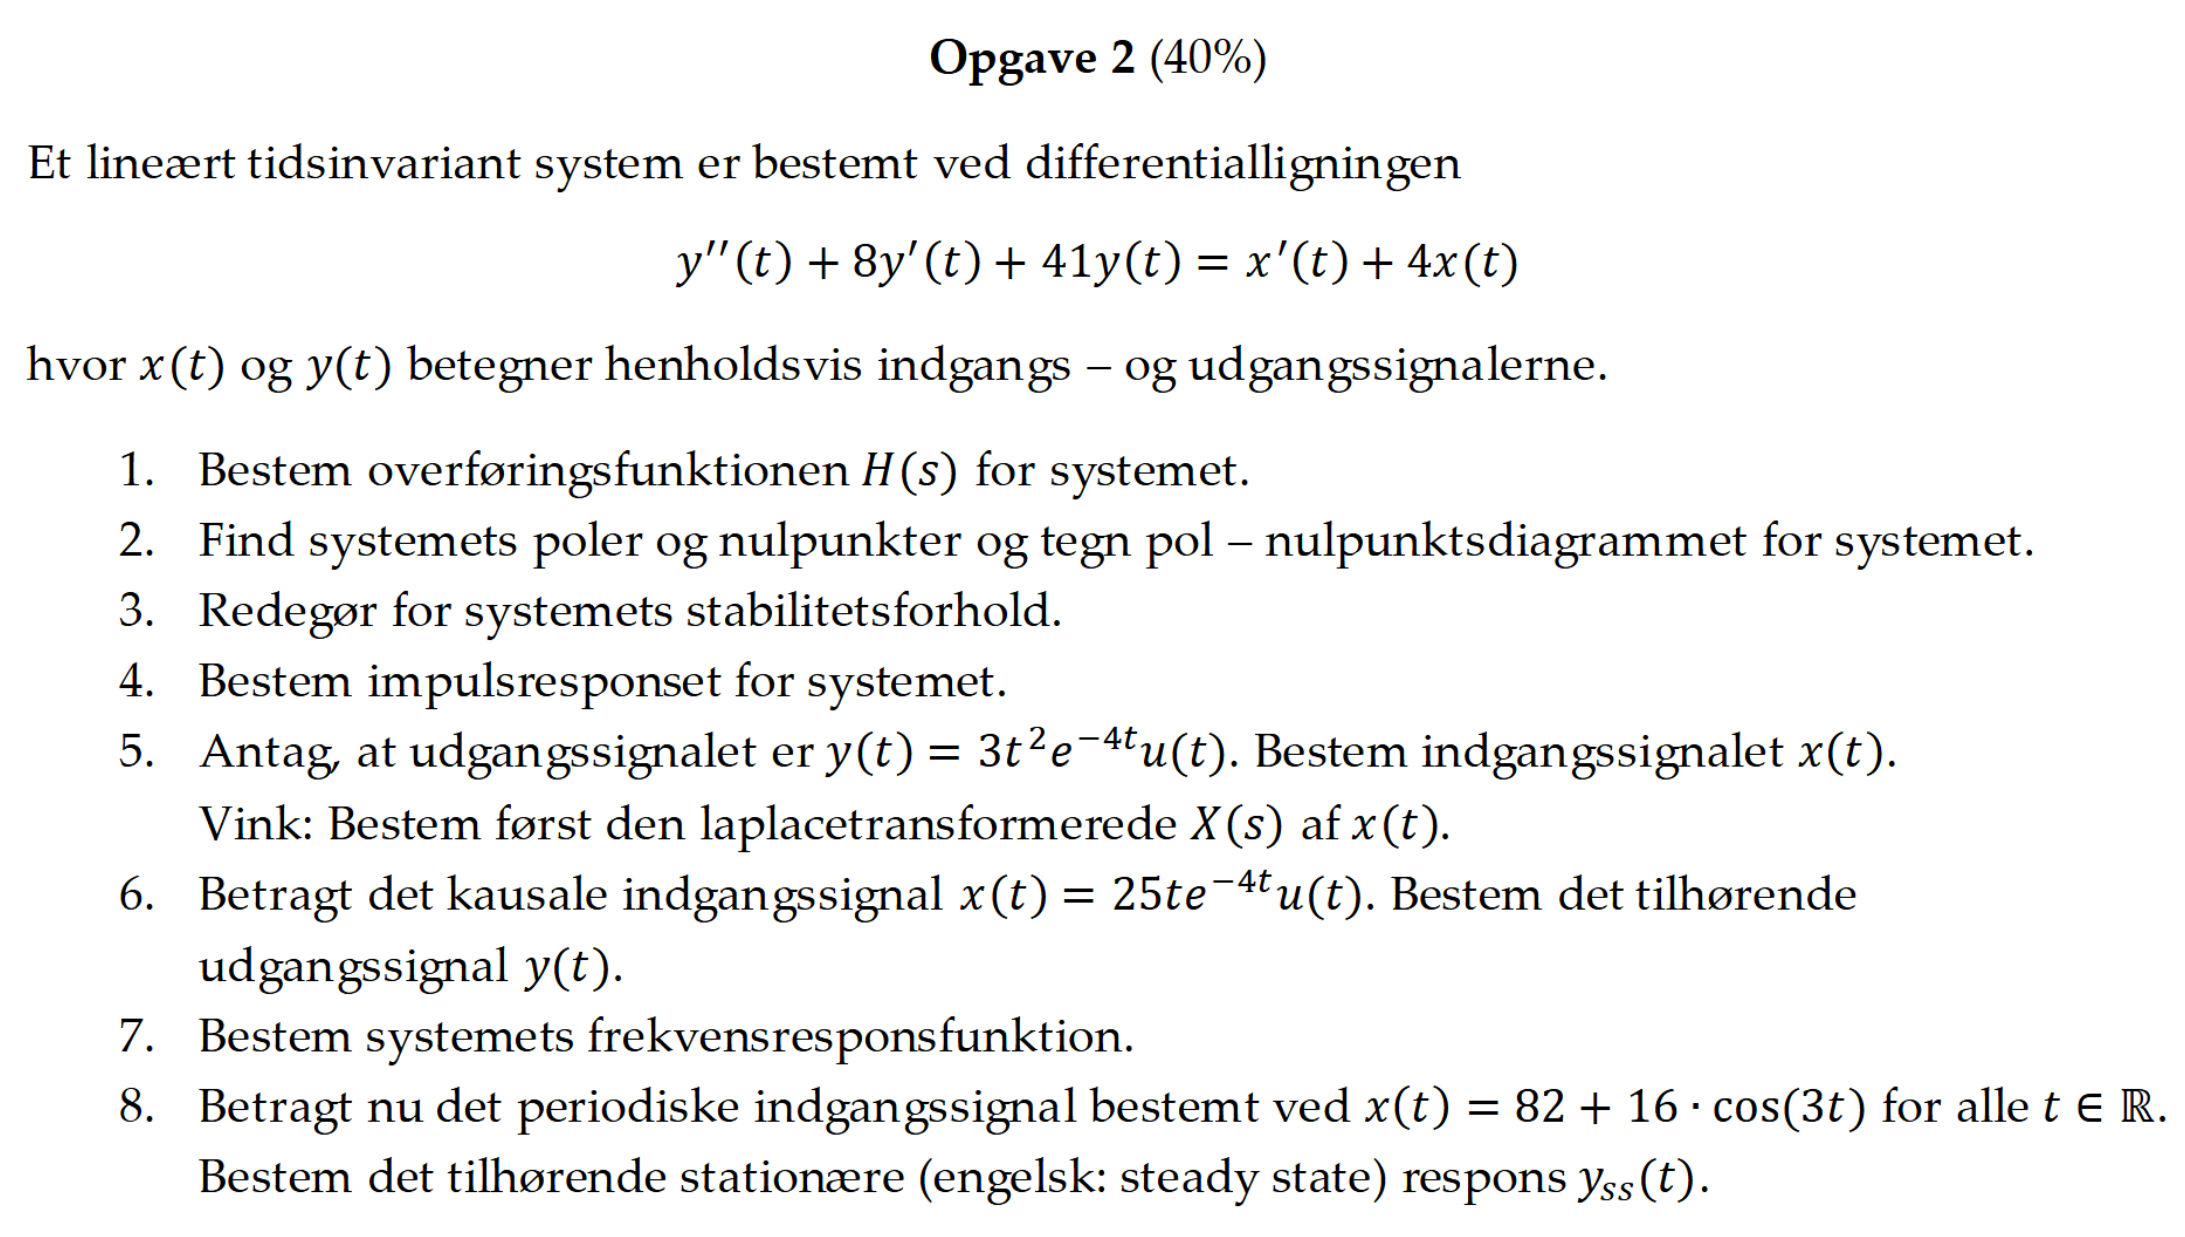

clear all; clc;

### 1. Bestem overføringsfunktionen 𝐻(𝑠) for systemet.

disp('=================================================================');
disp('OPGAVE 1: Bestem overføringsfunktionen 𝐻(𝑠) for systemet.');
disp('=================================================================');
disp(' ');

% Definerer koefficienterne for output og input
a = [1, 8, 41]; % Koefficienter for y'', y', y
b = [1, 4];     % Koefficienter for x', x

% Beregn overføringsfunktionen
[num, den, ~] = ElektroMatBibTrinvis.diffLigningTilOverfoeringsfunktionMedForklaring(b, a);

% Vis resultatet symbolsk
syms s;

H_s = poly2sym(num, s) / poly2sym(den, s);
disp(['H(s) = ' char(H_s)]);
disp(' ');

### 2. Find systemets poler og nulpunkter og tegn pol – nulpunktsdiagrammet for systemet

disp('=================================================================');
disp('OPGAVE 2: Find systemets poler og nulpunkter og tegn pol – nulpunktsdiagrammet for systemet');
disp('=================================================================');
disp(' ');

[poler, nulpunkter, stabilitet, ~] = ElektroMatBibTrinvis.polNulpunktsDiagramMedForklaring(num, den, 'LTI System');

### 3. Redegør for systemets stabilitetsforhold

disp('=================================================================');
disp('OPGAVE 3: Redegør for systemets stabilitetsforhold');
disp('=================================================================');
disp(' ');

disp(['Status: ' stabilitet.status]); % Dette burde vi godt kunne svare på ;-)

### 4. Bestem impulsresponset for systemet.

disp('=================================================================');
disp('OPGAVE 4: Bestem impulsresponset for systemet.');
disp('=================================================================');

% Beregn systemets impulsrespons
[t, y, impulsForklaring] = ElektroMatBibTrinvis.beregnStepresponsMedForklaring(num, den, [0, 10]);

% Du kan også beregne impulsresponset ved invers Laplace-transformation af H(s)
syms s t;
H_s_sym = poly2sym(num, s) / poly2sym(den, s);
[h_t, invLapForklaring] = ElektroMatBibTrinvis.inversLaplaceMedForklaring(H_s, s, t);

### 5. Antag, at udgangssignalet er $y\left(\textrm{𝑡}\right)=3{\textrm{𝑡}}^2 {\textrm{𝑒}}^{-4t} \textrm{𝑢}\left(\textrm{𝑡}\right)$. Bestem indgangssignalet $x\left(t\right)$. Vink: Bestem først den laplacetransformerede $X\left(S\right)$ af $x\left(t\right)$.

disp('=================================================================');
disp('OPGAVE 5: Bestem impulsresponset for systemet.');
disp('=================================================================');

% Definér udgangssignalet
syms t s;
y_t = 3*t^2*exp(-4*t);

% Beregn Laplace-transformationen af y(t)
[Y_s, lapForklaring] = ElektroMatBibTrinvis.laplaceMedForklaring(y_t, t, s);

% Find H(s) symbolsk
H_s_sym = poly2sym(num, s) / poly2sym(den, s);

% Beregn X(s) = Y(s)/H(s)
X_s = Y_s / H_s_sym;
X_s = simplify(X_s);

% Find x(t) ved invers Laplace-transformation
[x_t, invLapForklaring] = ElektroMatBibTrinvis.inversLaplaceMedForklaring(X_s, s, t);

### 6. Betragt det kausale indgangssignal $x\left(t\right)=25{\textrm{te}}^{-4t} u\left(t\right)$. Bestem det tilhørende udgangssignal $y\left(t\right)$.

### 7. Bestem systemets frekvensresponsfunktion.

### 8. Betragt nu det periodiske indgangssignal bestemt ved $x\left(t\right)=82+16*\cos \left(3t\right)$ for alle $\textrm{𝑡}\in \mathbb{R}$. Bestem det tilhørende stationære (engelsk: steady state) respons $y_{\textrm{ss}} \left(t\right)$.

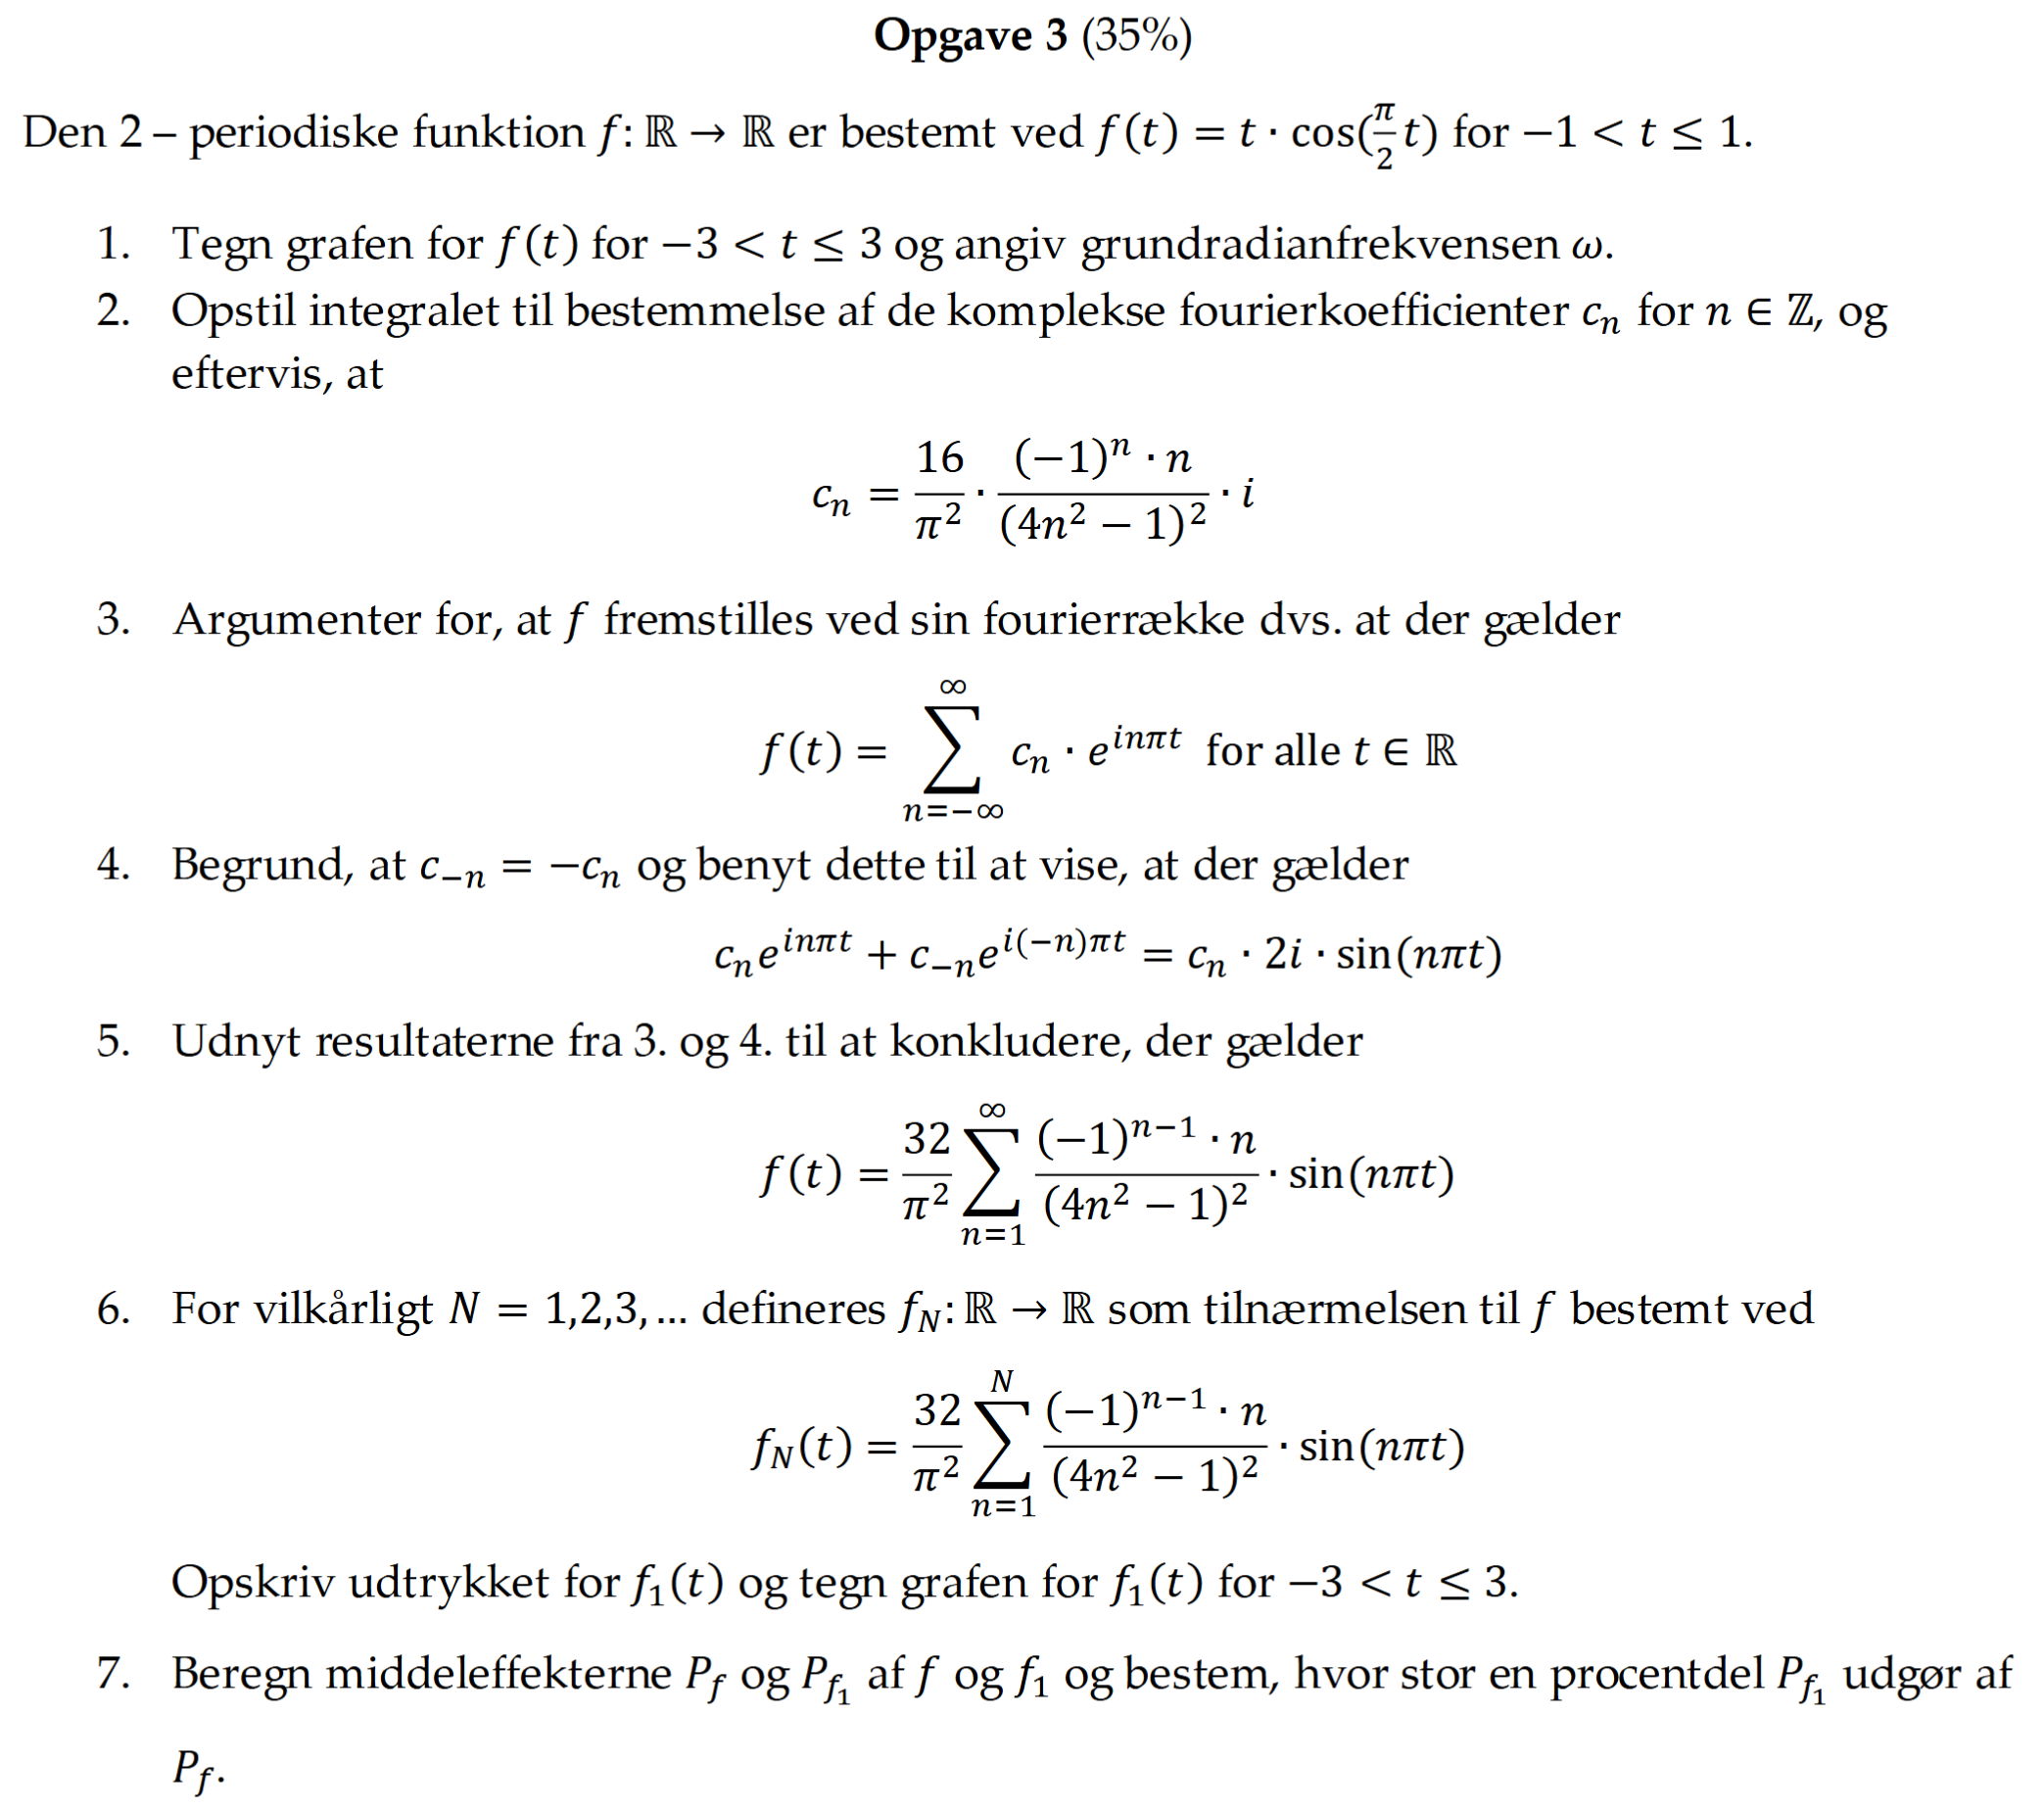

1. Tegn grafen for 𝑓(𝑡) for −3 < 𝑡 ≤ 3 og angiv grundradianfrekvensen 𝜔.

2. Opstil integralet til bestemmelse af de komplekse fourierkoefficienter 𝑐𝑛 for 𝑛 ∈ ℤ, og eftervis, at $c_n =\frac{16}{\pi^2 }=\frac{{\left(-1\right)}^n *n}{{\left(4n^2 -1\right)}^2 }*i$

3. Argumenter for, at 𝑓 fremstilles ved sin fourierrække dvs. at der gælder

4. 

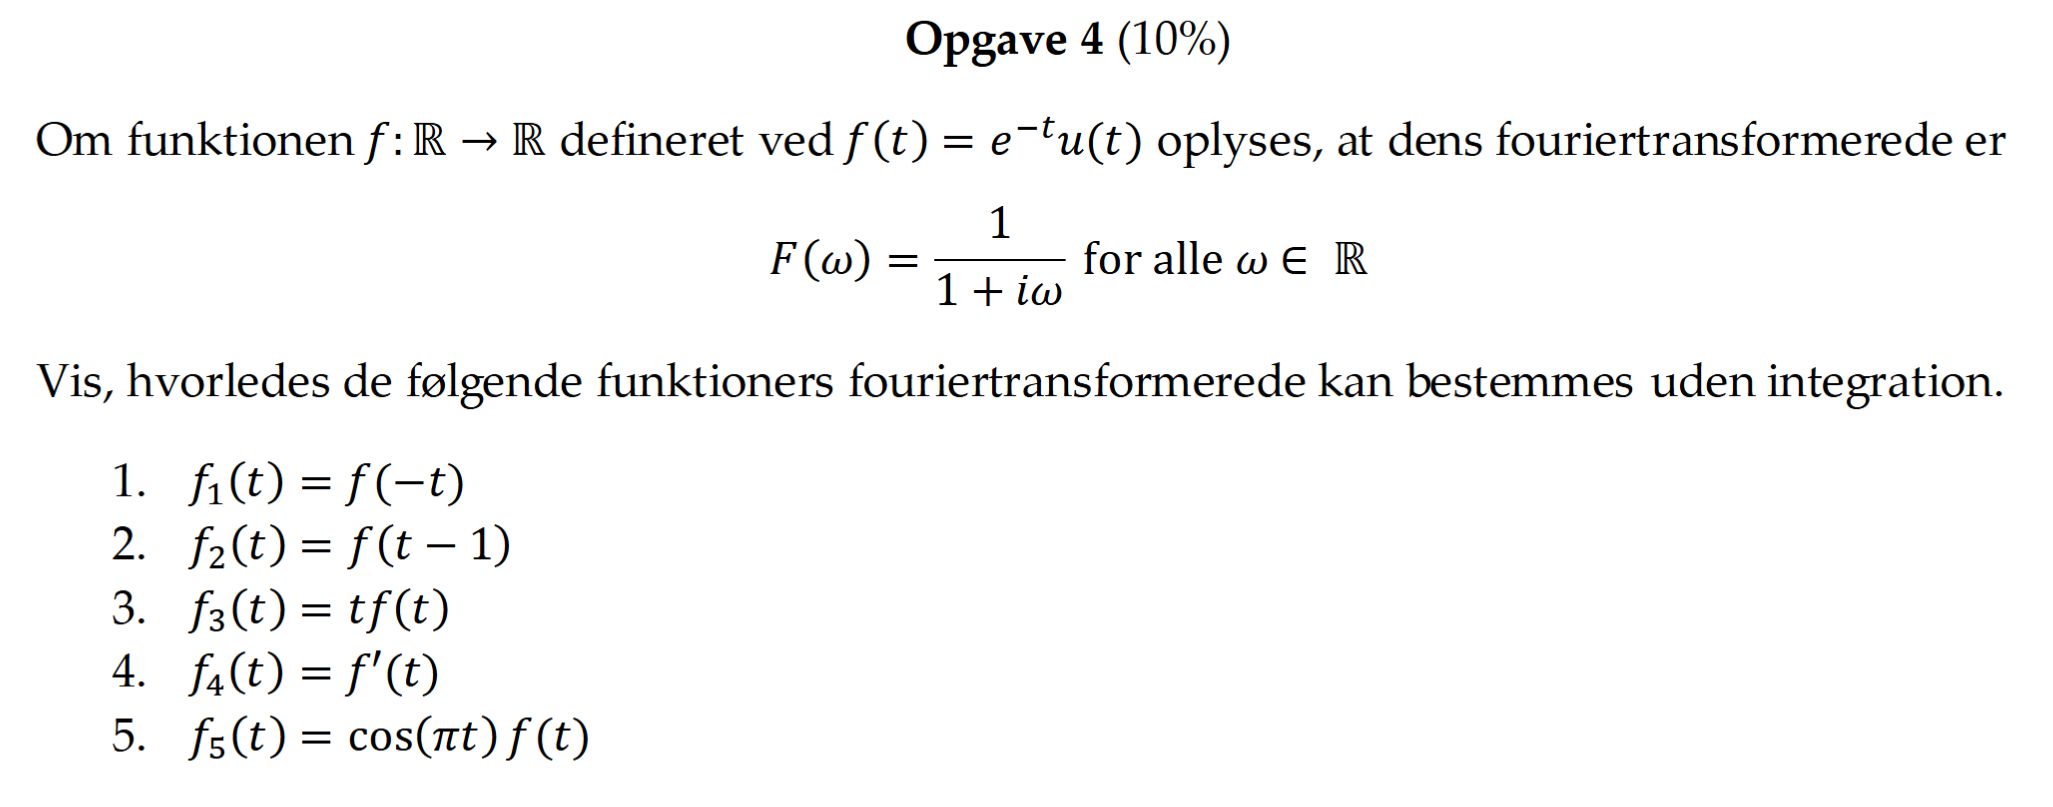

clear all; clc;

syms t omega;

%% Oprindelig funktion f(t) = sgn(t)e^(5it)u(t)
f_original = exp(-t) * heaviside(t);

### 1. 

disp('=================================================================');
disp('DELOPGAVE 1: f₁(t) = d²f(t)/dt²');
disp('=================================================================');
disp(' ');

% Anden afledte
[F1, forklaring1] = ElektroMatBibTrinvis.fourierAfledtMedForklaring(f_original, t, omega, 2);
disp(' ');
disp('SVAR PÅ DELOPGAVE 1:');
disp('===================');
disp(['F₁(ω) = ' char(F1)]);
disp(' ');

### 2. 

disp('=================================================================');
disp('DELOPGAVE 2: f₂(t) = (-it)³f(t)');
disp('=================================================================');
disp(' ');

% Tid-multiplikation med (-it)³
[F2, forklaring2] = ElektroMatBibTrinvis.fourierTidMultiplikationMedForklaring(f_original, t, omega, 3, true);
disp(' ');
disp('SVAR PÅ DELOPGAVE 2:');
disp('===================');
disp(['F₂(ω) = ' char(F2)]);
disp(' ');

### 3.

disp('=================================================================');
disp('DELOPGAVE 3: f₃(t) = f(3t - 10)');
disp('=================================================================');
disp(' ');

% Skalering og forskydning
[F3, forklaring3] = ElektroMatBibTrinvis.fourierSkaleringMedForklaring(f_original, t, omega, 3, 10);
disp(' ');
disp('SVAR PÅ DELOPGAVE 3:');
disp('===================');
disp(['F₃(ω) = ' char(F3)]);
disp(' ');

### 4.

disp('=================================================================');
disp('DELOPGAVE 4: f₄(t) = ∫₋∞ᵗ f(τ)dτ');
disp('=================================================================');
disp(' ');

% Integration
[F4, forklaring4] = ElektroMatBibTrinvis.fourierIntegralMedForklaring(f_original, t, omega);
disp(' ');
disp('SVAR PÅ DELOPGAVE 4:');
disp('===================');
disp(['F₄(ω) = ' char(F4)]);
disp(' ');

### 5.

disp('=================================================================');
disp('DELOPGAVE 5: f₅(t) = F(t)');
disp('=================================================================');
disp(' ');

% Fourier af Fourier
[F5, forklaring5] = ElektroMatBibTrinvis.fourierAfFourierMedForklaring(f_original, t, omega);
disp(' ');
disp('SVAR PÅ DELOPGAVE 5:');
disp('===================');
disp(['F₅(ω) = ' char(F5)]);
disp(' ');